syms s J r r2 th th2 k k2 m g fa w wp b thp 

thp=w;
wp=(1/(J+m*r*r))*(r*(fa+m*g)-b*w-k*r*r*th-((r*r)/(r2*r2))*k2*th);
xe=[th,w];
% salida %%%
th2=(r/r2)*th;
%%%%%%%%%%%%
ts=2;
zeta=1;
A=jacobian([thp,wp],xe)

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{k\,r^{2}+\frac{k_{2}\,r^{2}}{{r_{2}}^{2}}}{m\,r^{2}+J} & -\frac{b}{m\,r^{2}+J} \end{array}\right)$$

B=jacobian([thp,wp],fa)

$$B = \left(\begin{array}{c} 0\\ \frac{r}{m\,r^{2}+J} \end{array}\right)$$

C=jacobian(th2,xe)

$$C = \left(\begin{array}{cc} \frac{r}{r_{2}} & 0 \end{array}\right)$$

D=jacobian(th2,fa)

$$D = 0$$


F_transSimb=C*(inv(s*eye(2)-A))*B+D

$$F\_transSimb = \frac{r^{2}\,r_{2}}{m\,r^{2}\,{r_{2}}^{2}\,s^{2}+k\,r^{2}\,{r_{2}}^{2}+k_{2}\,r^{2}+J\,{r_{2}}^{2}\,s^{2}+b\,{r_{2}}^{2}\,s}$$


J=0.01

J = 0.0100

r=0.1

r = 0.1000

r2=r/2

r2 = 0.0500

k=1

k = 1

k2=0.5

k2 = 0.5000

b=0.1

b = 0.1000

g=9.81

g = 9.8100

m=1

m = 1

%%%%%%%%%%%%%%%%%%%%%%
A=double(eval(A))

A =          0    1.0000
 -100.5000   -5.0000


B=double(eval(B))

B =          0
    5.0000


C=double(eval(C))

C =      2     0


D=double(eval(D))

D = 0

[num,den]=ss2tf(A,B,C,D)

num =          0         0   10.0000


den =     1.0000    5.0000  100.5000


ft=tf(num,den)

ft =
 
         10
  -----------------
  s^2 + 5 s + 100.5
 
Continuous-time transfer function.



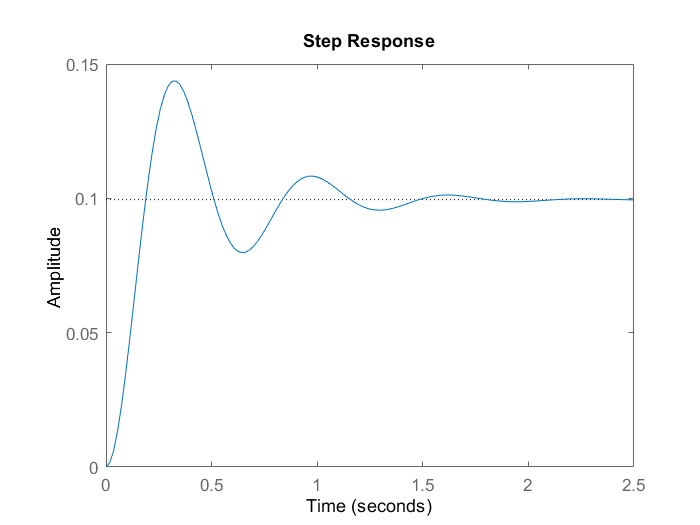

step(ft)

%%%%%%%%%%%%%%%%%%%%%
wn=4/(ts*zeta)

wn = 2

polos=roots([1 2*zeta*wn wn^2])

polos =     -2
    -2


K=acker(A,B,polos)

K =   -19.3000   -0.2000


%%%%%%%%%%%%%%%%%%%%%%Ess=0 Parabola
polosEss=conv(polos,[1 10*wn*zeta])

polosEss =     -2   -42   -40


polosEss=conv(polosEss,[1 10*wn*zeta])

polosEss =     -2   -82  -880  -800


polosEss=conv(polosEss,[1 10*wn*zeta])

polosEss =           -2        -122       -2520      -18400      -16000


Aempaq=[A(1,1),A(1,2),0,0,0;A(2,1),A(2,2),0,0,0;0,0,0,1,0;0,0,0,0,1;-C(1,1),-C(1,2),0,0,0]

Aempaq =          0    1.0000         0         0         0
 -100.5000   -5.0000         0         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000
   -2.0000         0         0         0         0


Bempaq=[B(1,1);B(2,1);0;0;0]

Bempaq =          0
    5.0000
         0
         0
         0


K1=acker(Aempaq,Bempaq,polosEss)

K1 = 	1.0e+13 *

    0.0000    0.0000   -1.8102   -0.9209   -0.0079


%%%%%%Observador
tsa=ts/10;
wna=4/(tsa*zeta)

wna = 20

obs=[C;C*A]

obs =      2     0
     0     2


det(obs)

ans = 4

pdo=conv([1 2*tsa*zeta wna^2],[1 10*wna*zeta])

pdo = 	1.0e+04 *

    0.0001    0.0200    0.0480    8.0000


phia= A^3+pdo(2)*A^2+pdo(3)*A+pdo(4)*eye(2)

phia = 	1.0e+04 *

    6.0362   -0.0597
    6.0049    6.3350


L=phia*(inv(obs))*[1/r;0]

L = 	1.0e+05 *

    3.0181
    3.0024


%%%%%%%%% tm=0.5s
tm=0.5

tm = 0.5000

polosEssT=conv(polosEss,[1 10*wn*zeta])

polosEssT =           -2        -162       -4960      -68800     -384000     -320000


polosEssT=conv(polosEssT,[1 10*wn*zeta])

polosEssT =           -2        -202       -8200     -168000    -1760000    -8000000    -6400000


ftdelay=tf([1],[(tm^2)/2 tm 1])

ftdelay =
 
            1
  ---------------------
  0.125 s^2 + 0.5 s + 1
 
Continuous-time transfer function.



ft2=ft*ftdelay

ft2 =
 
                          10
  ---------------------------------------------------
  0.125 s^4 + 1.125 s^3 + 16.06 s^2 + 55.25 s + 100.5
 
Continuous-time transfer function.



[A1,B1,C1,D1]=tf2ss(10,[0.125,1.125,16.06,55.25,100.5])

A1 =    -9.0000 -128.4800 -442.0000 -804.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B1 =      1
     0
     0
     0


C1 =      0     0     0    80


D1 = 0

Aempaq1=[A1(1,1),A1(1,2),A1(1,3),A1(1,4),0,0,0;A1(2,1),A1(2,2),A1(2,3),A1(2,4),0,0,0;A1(3,1),A1(3,2),A1(3,3),A1(3,4),0,0,0;A1(4,1),A1(4,2),A1(4,3),A1(4,4),0,0,0;0,0,0,0,0,1,0;0,0,0,0,0,0,1;-C1(1,1),-C1(1,2),-C1(1,3),-C1(1,4),0,0,0]

Aempaq1 =    -9.0000 -128.4800 -442.0000 -804.0000         0         0         0
    1.0000         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000
         0         0         0  -80.0000         0         0         0


Bempaq1=[B1(1,1);B1(2,1);B1(3,1);B1(4,1);0;0;0]

Bempaq1 =      1
     0
     0
     0
     0
     0
     0


KDelay=acker(Aempaq1,Bempaq1,polosEssT)

KDelay = 	1.0e+29 *

    0.0000    0.0000    0.0000    0.0002   -6.2690   -3.1663   -0.0159
